%calculating the mean first passage time using Gillespie simulations 
%to investigate effect of invader toehold length on DNA/DNA TMSD kinetics
%including spontaneous incumbent dissociation

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

N = 10 %number of simulations

N = 10

avr_first_pass_time = zeros(1,15)

avr_first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_first_pass_time = zeros(15, N)

ind_first_pass_time =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


k_eff = zeros(1, 15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ind_k_eff = zeros(15, N)

ind_k_eff =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


std_err_fpt = zeros(1, 15)

std_err_fpt =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_k_eff = zeros(1, 15)

std_err_k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


std_err_log_k = zeros(1,15)

std_err_log_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through invader toehold lengths
for g = 1:15

    %define forward and reverse transition rates
    k_AA = 0;
    k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
    k_B1A = k_bp * exp(dGbp/(R*temp))
    k_BC1ij = k_bp;
    k_BC1ji = k_bp * exp(dGbp/(R*temp));
    k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
    k_Cf = k_bp * exp(-dGbm/(R*temp))
    k_Cr = k_bp * exp(-dGbm/(R*temp));
    k_CD = k_bp * exp(-dGbm/(R*temp));
    k_DC = 0 
    k_DD = 1
    
    first_pass_time = zeros(1,N)
    
    if g == 1
        %create arrays of forward and reverse transition rates
        Kf = [k_AB1, k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, k_Cr, repmat(k_Cr, [1 b-2]), k_DC]
        
        %define spontaneous incumbent dissociation rates
        Koff = [0, 0]; 
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])
    else
        %create arrays of forward and reverse transition rates
        Kf = [k_AB1, k_BC1ij, repmat(k_BC1ij, [1, g-2]), k_C1f, repmat(k_Cf, [1, b-2]), k_CD, k_DD]
        Kb = [k_AA, k_B1A, repmat(k_BC1ji, [1, g-2]), k_BC1ji, k_Cr, repmat(k_Cr, [1, b-2]), k_DC]
    
        %define spontaneous incumbent dissociation rates
        Koff = [repmat(0, [1, g+1])];
        for n = b-1:-1:1
            Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
        end
        Koff = horzcat(Koff, [0])      
    end
    
    totalrate = Kf + Kb + Koff; %define total rate
    Pf = Kf./totalrate; %define probability of forward transition 
    Poff = Koff./totalrate; %define probability of spontaneous incumbent dissociation 
    Pb = 1- (Pf + Poff); %define probability of reverse transition 
    %loop through simulations
    for n = 1:N 
        state = 1; %initial state
        t = 0; %initial time
        %restrict to possible states
        while (state >=1 && state < (2 + g + b)) 
            t = t - (1/totalrate(state))*log(rand()); %calculate time for transition 
            prob = rand();
            %select transition 
            if prob <= Pf(state) 
                state = state +1; %update state forward
            elseif prob > Pf(state) && prob < Pf (state) + Poff(state)
                state = 2 + g + b; %update state for spontaneous incumbent dissociation 
            else 
                state = state -1;%update state backward
            end
        end
        first_pass_time(n) =  t; 
        ind_first_pass_time(g,n) = first_pass_time(n);
        ind_k_eff(g,n) = 1/(first_pass_time(n)*(5*10^-8));
    end
    std_err_fpt(g) = std(ind_first_pass_time(g, :))/sqrt(N); %calculate standard error
    std_err_k_eff(g) = std(ind_k_eff(g, :))/sqrt(N);
    std_err_log_k(g) = std(log10(ind_k_eff(g,:))/sqrt(N));
    avr_first_pass_time(g) = mean(first_pass_time) %calculate average first passage time
    k_eff(g) = 1/(mean(first_pass_time)*(5*10^-8)) %calculate effective rate constant
end

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+04 *

    0.0000    0.0902    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0001


Kb = 	1.0e+06 *

         0    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =    36.4129         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367         0         0         0         0         0         0         0         0         0         0         0         0         0


k_eff =    36.4129  594.0050         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367    0.0303         0         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+03 *

    0.0364    0.5940    6.6099         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367    0.0303    0.0021         0         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+04 *

    0.0036    0.0594    0.6610    9.6695         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367    0.0303    0.0021    0.0001         0         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0000    0.0006    0.0066    0.0967    1.7465         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367    0.0303    0.0021    0.0001    0.0001         0         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0000    0.0006    0.0066    0.0967    1.7465    3.3625         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb = 	1.0e+06 *

         0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff = 	1.0e+06 *

         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time = 	1.0e+05 *

    5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000         0         0         0         0         0         0         0         0


k_eff = 	1.0e+06 *

    0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf = 	1.0e+07 *

    0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff =          0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001         0         0         0         0         0         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0000


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330         0


Koff =          0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448         0


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000         0         0         0         0         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0023    0.0281    0.3496    4.3448


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001         0         0         0         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001         0         0         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490    3.9567         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001         0         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490    3.9567    3.0228         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000         0         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490    3.9567    3.0228    4.3265         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000         0


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490    3.9567    3.0228    4.3265    4.0072         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_DC = 0

k_DD = 1

first_pass_time =      0     0     0     0     0     0     0     0     0     0


Kf =     0.0000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033


Kb =          0    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330


Koff =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508


avr_first_pass_time =     5.4926    0.3367    0.0303    0.0021    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0000    0.0001


k_eff =     0.0000    0.0006    0.0066    0.0967    1.7465    3.3625    5.6060    2.9285    6.3397    3.8490    3.9567    3.0228    4.3265    4.0072    2.0065


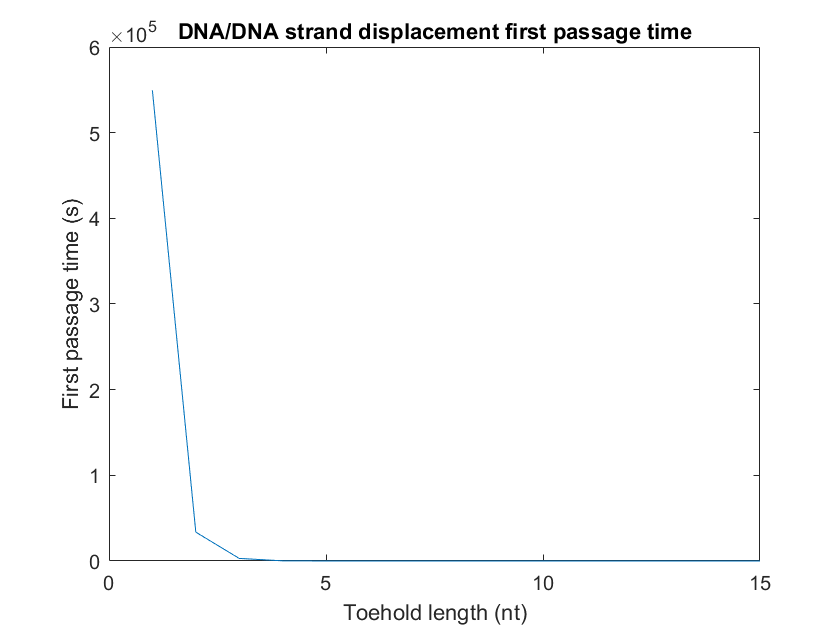

plot(1:15, avr_first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

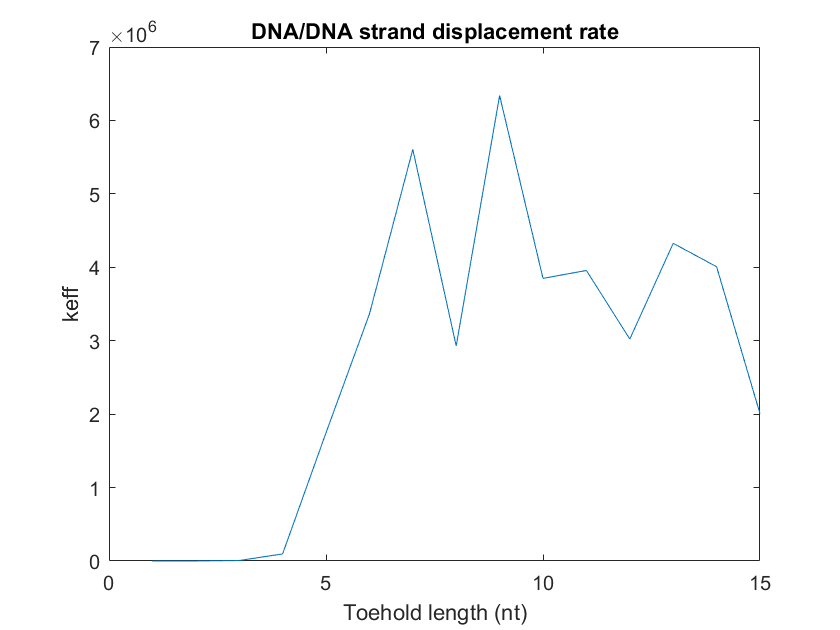


plot(1:15, k_eff)
ylabel('keff')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

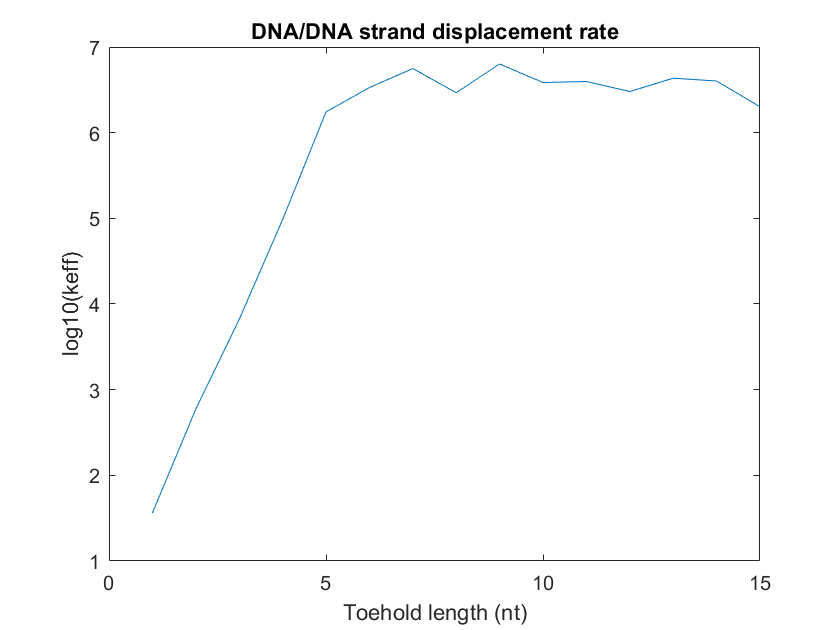


plot(1:15, log10(k_eff))
ylabel('log10(keff)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement rate')

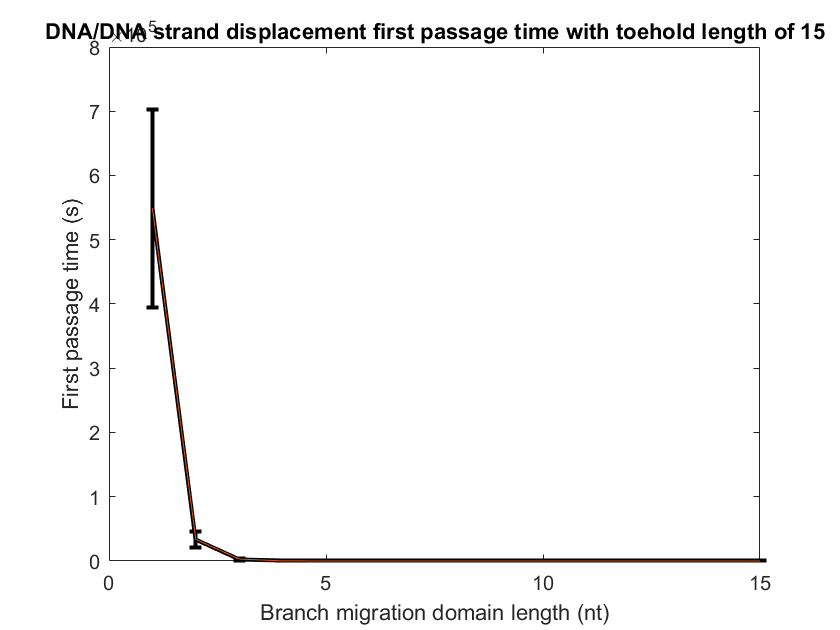


errorbar(1:15, avr_first_pass_time, std_err_fpt , 'k', 'linewidth', 2)
hold on
plot(1:15, avr_first_pass_time, 'linewidth', 0.5)
xlabel('Branch migration domain length (nt)')
ylabel('First passage time (s)')
title('DNA/DNA strand displacement first passage time with toehold length of ' + string(g))

hold off

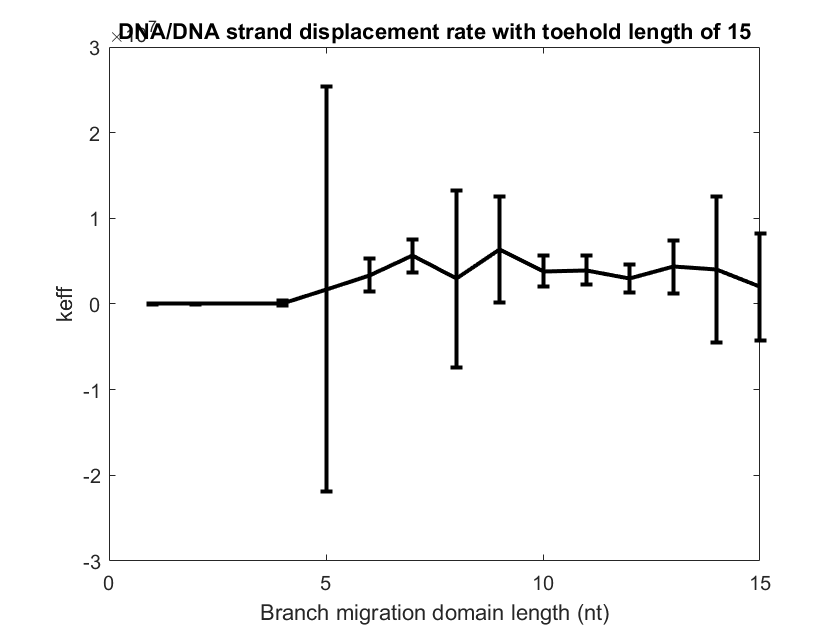


errorbar(1:15, k_eff, std_err_k_eff, 'k', 'linewidth', 2)
xlabel('Branch migration domain length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate with toehold length of ' + string(g))
hold off


dark_blue = 1/255*[31,120,180];
light_blue  = 1/255*[146,197,222];
rred = 1/255*[202,0,32];

ax = gca;
errorbar(1:15, log10(k_eff), std_err_log_k, 'Color', rred, 'linewidth', 2)
hold on
plot(1:15, log10(ana_k_eff), 'Color', dark_blue, 'linewidth', 2)
scatter(1:15, log10(ana_k_eff), [], dark_blue, 'filled')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


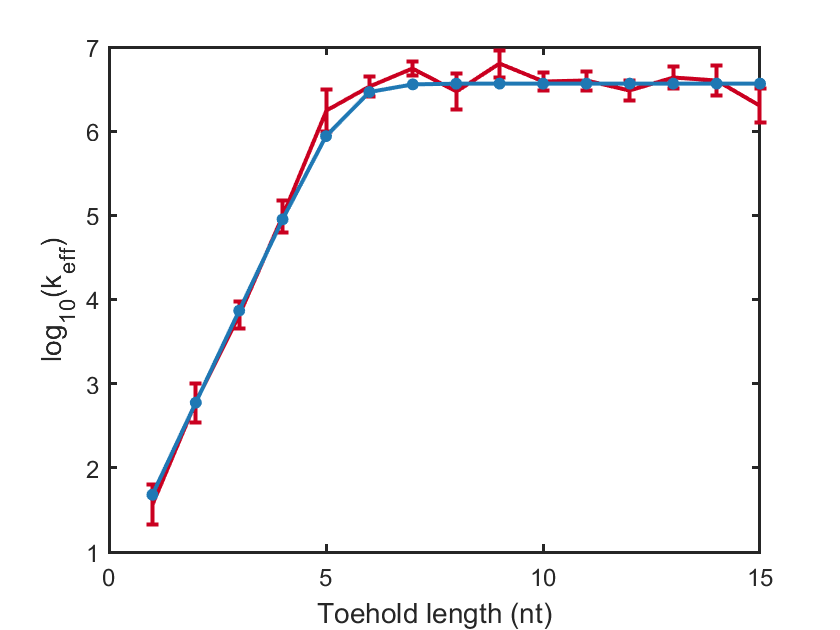

xlabel('Toehold length (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
%title('DNA/DNA toehold-mediated strand displacement rate')
hold off